clc; clear all; close all;

% Specify the folder containing the audio files
dataFolder = 'C:\Users\aniru\OneDrive\Documents\MFC\emotion_dataset'; % Update with your path
audioFiles = dir(fullfile(dataFolder, '*.wav')); % Adjust file type if needed

% Initialize variables for features and labels
features = [];
labels = [];

% Extract features and labels from audio files (training set)
for i = 1:round(0.8 * length(audioFiles))
    [~, name, ~] = fileparts(audioFiles(i).name);
    if contains(name, 'HAP')
        [audioData, fs] = audioread(fullfile(dataFolder, audioFiles(i).name));
        coeffs = mfcc(audioData, fs);
        meanCoeffs = mean(coeffs, 1);
        features = [features; meanCoeffs];
        labels = [labels; 1];
    elseif contains(name, 'SAD')
        [audioData, fs] = audioread(fullfile(dataFolder, audioFiles(i).name));
        coeffs = mfcc(audioData, fs);
        meanCoeffs = mean(coeffs, 1);
        features = [features; meanCoeffs];
        labels = [labels; 0];
    end
end

% Normalize training features
features = zscore(features)

features =     0.7117    1.2545   -0.6025   -2.4551    1.8315    1.1999   -1.1629   -0.5488    2.0263   -1.8337   -1.3175    0.9439   -3.2642    1.3368
   -0.6222   -0.1020   -0.8302   -1.9745    2.0261    1.8921   -0.3513    0.0392    1.5266   -0.7756    0.0380    0.1755   -1.5590    1.9490
    2.1822    2.8398   -0.9816   -3.2011   -1.8260   -1.3143    0.1758   -1.5540    0.7342   -3.2006   -0.3248    1.5607   -3.3795    1.9395
   -0.3077    0.3658   -0.2974   -1.6992    0.0342   -0.2573    2.5112   -0.5292    1.3133   -2.6757    0.3384    1.0337   -2.4153    2.6177
    0.0882    0.7299   -0.3313   -1.9942   -0.3660   -0.2639    1.5837   -0.4920    0.6173   -2.9209    0.0554    1.0497   -1.5732    2.2308
   -0.6105   -0.2275    0.5248   -1.4984    0.2412    0.8952    0.1335    0.1161    0.9042   -1.5440    0.1666    0.9030   -1.2704    1.2605
   -0.8666   -0.2710    0.5353   -1.1296   -0.3677    0.7270    1.1096   -0.0424    1.2661   -2.0493   -0.1450    0.3540   -0.7313    0.7779
  


% Apply SVD to training features
[U, S, V] = svd(features, 'econ');
k = 2; % Increased number of dimensions to retain more information
U_reduced = U(:, 1:k);
S_reduced = S(1:k, 1:k);
V_reduced = V(:, 1:k);

% Reduced training features
reduced_features = U_reduced * S_reduced;

% Test features and labels extraction
features_test = [];
labels_test = [];
for i = round(0.8 * length(audioFiles)) + 1:length(audioFiles)
    [~, name1, ~] = fileparts(audioFiles(i).name);
    if contains(name1, 'HAP')
        [audioData1, fs1] = audioread(fullfile(dataFolder, audioFiles(i).name));
        coeffs1 = mfcc(audioData1, fs1);
        meanCoeffs1 = mean(coeffs1, 1);
        features_test = [features_test; meanCoeffs1];
        labels_test = [labels_test; 1];
    elseif contains(name1, 'SAD')
        [audioData1, fs1] = audioread(fullfile(dataFolder, audioFiles(i).name));
        coeffs1 = mfcc(audioData1, fs1);
        meanCoeffs1 = mean(coeffs1, 1);
        features_test = [features_test; meanCoeffs1];
        labels_test = [labels_test; 0];
    end
end

% Normalize test features
features_test = zscore(features_test)

features_test =     0.0511    0.0486    0.9986    0.0228    0.5653   -0.1562   -1.0910   -1.4649   -1.8279    1.4920   -0.2740   -0.1961    1.4944   -0.2598
    0.0724    0.0602   -0.8969    0.3193    1.6061   -0.4875   -1.0162   -0.4208   -1.6585    0.8879   -2.1338    0.7175    0.5997    0.7470
    0.0494    0.0512   -0.6696    0.9418    0.6919    0.2829   -1.5244   -1.3088   -1.9076    0.1460   -0.9569   -0.1235    1.3421    0.5031
    0.0845    0.0643    0.7913   -0.5083    0.9388   -1.1955    0.8916   -0.2901   -2.3082    0.6721   -1.2315    1.1830   -0.0155    0.0728
    0.0487    0.0470    0.8777    0.6875    0.0546   -0.4194    0.3470   -0.3374   -2.3399   -0.1598    0.1055    1.2012    0.7952   -0.2958
    0.0993    0.0776   -0.9564   -0.5881    2.4376   -1.7550   -0.6518   -0.9303   -0.6261   -2.7048    0.6185    0.7395    1.0561   -0.0912
    0.0672    0.0599   -0.6708    0.0169    2.3470   -1.0574   -1.4489   -0.5328   -0.7406   -1.8878    0.5389    0.7450    0.7785    0.97


% Project test features onto SVD components
reduced_features_test = features_test * V_reduced;

% SVM with Hyperparameter Tuning
C_values = [0.1, 1, 10, 100]; % BoxConstraint values to test
bestAccuracy = 0;
bestModel = [];

for C = C_values
    % Train SVM
    SVM_model = fitcsvm(reduced_features, labels, ...
        'KernelFunction', 'rbf', ...
        'BoxConstraint', C, ...
        'Standardize', true);

    % Cross-validation
    cvSVMModel = crossval(SVM_model, 'KFold', 5);
    cvAccuracy = 1 - kfoldLoss(cvSVMModel, 'LossFun', 'classiferror');
    fprintf("C = %.2f, Cross-Validation Accuracy: %.2f%%\n", C, cvAccuracy * 100);

    % Store the best model
    if cvAccuracy > bestAccuracy
        bestAccuracy = cvAccuracy;
        bestModel = SVM_model;
    end
end

C = 0.10, Cross-Validation Accuracy: 81.11%
C = 1.00, Cross-Validation Accuracy: 81.21%
C = 10.00, Cross-Validation Accuracy: 81.06%
C = 100.00, Cross-Validation Accuracy: 80.62%



% Use the best model for testing
yp_test = predict(bestModel, reduced_features_test);

% Calculate test accuracy
test_accuracy = sum(yp_test == labels_test) / length(labels_test) * 100;
fprintf("Best Test Accuracy: %.2f%%\n", test_accuracy);

Best Test Accuracy: 77.01%



confMat = confusionmat(labels_test, yp_test);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

   195    60
    57   197



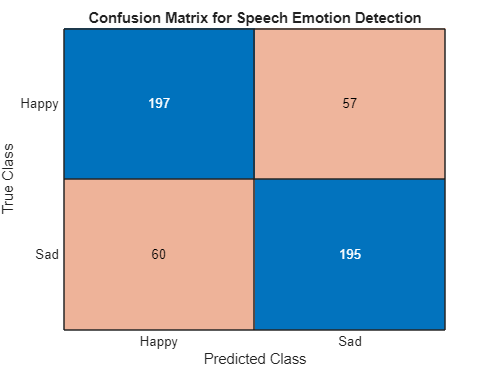


% Plot the confusion matrix
figure;
confusionchart(confMat, {'Sad', 'Happy'});
title('Confusion Matrix for Speech Emotion Detection');